# Testing

## Testing di Robustezza

### Testing sul numero di input

load mathwork200.mat;
[R, OUT, IN] = PageRank();

Error using PageRank (line 91)
Inserire come parametro di input la matrice G

### Testing sulla matrice G

#### Testo se è una matrice

G=rand(10,10,10);
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 96)
Il primo input deve essere una matrice.

#### Testo se è sparsa o vuota

G=rand(100,100);
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 98)
La matrice deve essere sparsa e non vuota.

G=[];
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 98)
La matrice deve essere sparsa e non vuota.

#### Testo se è quadrata

G=sparse(rand(100,50));
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 100)
La matrice deve essere quadrata.

#### Testo se è composta da elementi logical

G=sparse(rand(100,100));
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 102)
Gli elementi della matrice devono essere logici.

## Testing di Funzionamento

load mathwork200.mat;
[R, OUT, IN] = PageRank(G)

R =    0.001759217077077
   0.005536967249761
   0.004787988545060
   0.004798261903168
   0.004798261903168
   0.004787988545060
   0.004787988545060
   0.004787988545060
   0.004787988545060
   0.004787988545060


OUT =     20
    19
    19
    20
    20
    19
    19
    19
    19
    19


IN =      0
    18
    16
    16
    16
    16
    16
    16
    16
    16


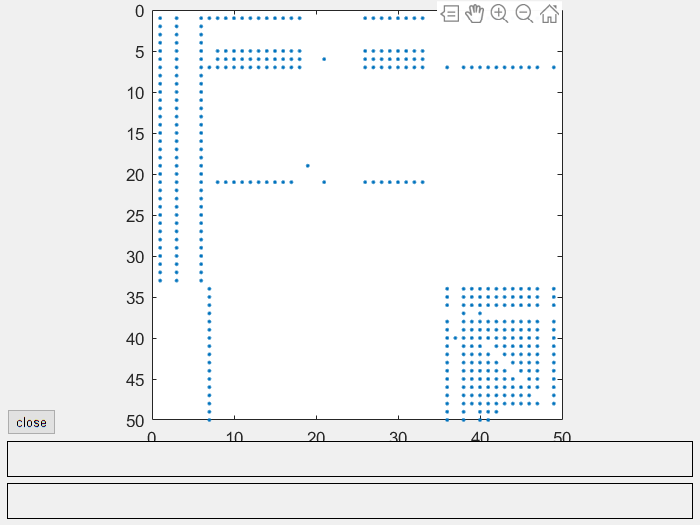

[U,G]=surfer('http://www.unina.it',50);

[R, OUT, IN] = PageRank(G)

R =    0.063631444211992
   0.011005910489649
   0.010721130453865
   0.011005910489649
   0.047022753614491
   0.082804654583314
   0.062376115639968
   0.011005910489649
   0.011005910489649
   0.011005910489649


OUT =     32
     0
    32
     0
     0
    32
    18
     5
     5
     5


IN =     34
     3
     2
     3
    22
    22
    34
     3
     3
     3


## Testing di Accuratezza

load repubblica.mat;
[R, OUT, IN] = PageRank(G);

R =    0.003664699397457
   0.010296841870834
   0.011167176684174
   0.013667655780723
   0.011275168181545
   0.011805652712293
   0.022636735178662
   0.011805652712293
   0.011805652712293
   0.093172404100900


OUT =     99
     0
     0
     0
     0
     0
     0
     0
     0
    98


IN =      0
    34
    37
    40
    37
    38
    39
    38
    38
    70


G=digraph(G);

Undefined function 'centrality' for input arguments of type 'char'.

pg_ranks=centrality(G,'pagerank');

## Esecuzione Script

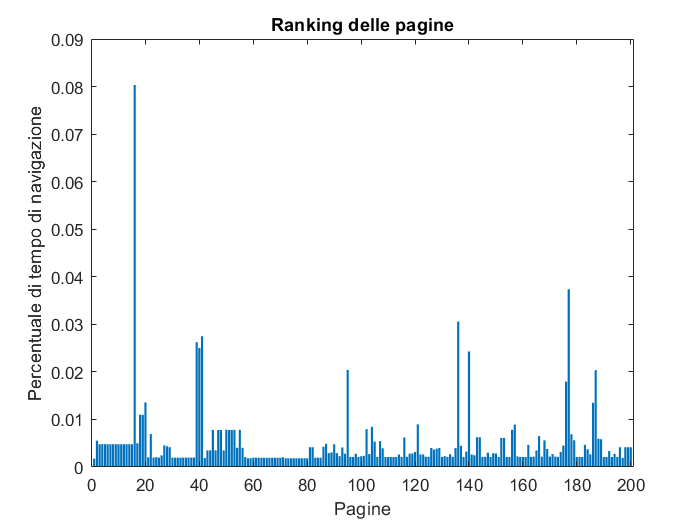

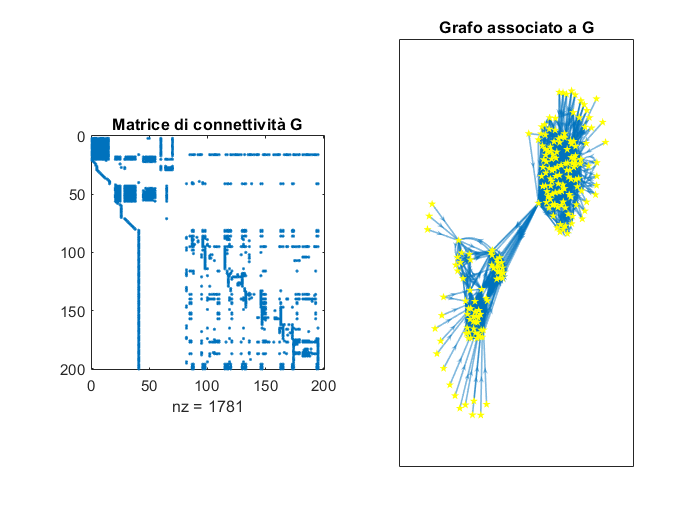

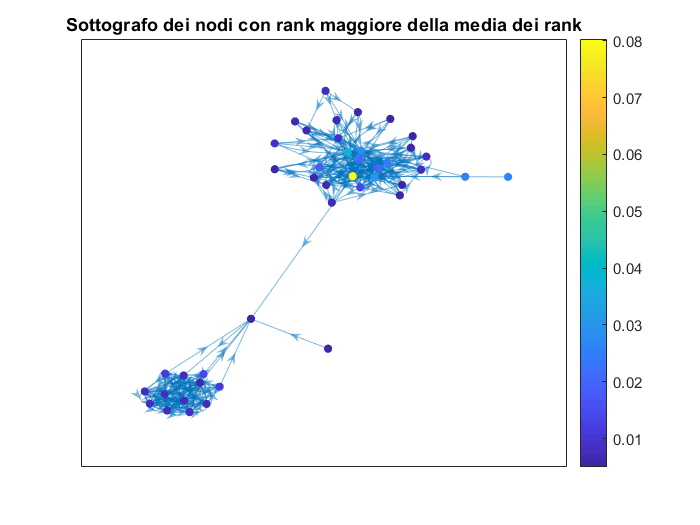

TOP15 = 15×3 table
                                                             Ranking          OUT    IN
                                                       ___________________    ___    __

    http://schema.org                                   0.0803187473922825      3    91
    http://schema.org/CreativeWork                      0.0373794993695825     14    43
    http://schema.org/Offer                             0.0305887665373424     14    31
    http://blog.schema.org                              0.0274852834350127    122    22
    http://schema.org/docs/about.html                    0.026260602816937      0     2
    http://github.com/schemaorg/schemaorg               0.0250318920006022      0     4
    http://schema.org/image                            

pagerankscript